# To generate single robot data for debug. 

clear;clc;
addpath("gendata_helper");
addpath("Tools");


## Generate Trajectory for one Robot


T_WORKING=200; %
dti=0.01; %The sample interval of the IMU/estimator(s), i.e. IMU's frequency is 100Hz
scale=1;

sigma_bg=0.01; 
sigma_ba=0.01; 
sigma_a=0.01; %%0.01
sigma_g=0.01;

b_g_real=[0.02,0.01,0.02];%bias 
b_a_real=[0.03,0.05,0.03];
g_real=[0;0;-9.81];


Position0=[0,0,0];
% Generate many landmarks
N_LANDMARKS=5;
landm_pos=10*randn(N_LANDMARKS,3)+Position0;
landmarks=[];
for uu=1:N_LANDMARKS
    T_f=eye(4);
    Rot1=randn(1,1)*3.14;
    Rot2=randn(1,1)*3.14;
    Rot3=randn(1,1)*3.14;
    Rot=angle2dcm(Rot1,Rot2,Rot3);
    T_f(1:3,1:3)=Rot;
    T_f(1:3,4) = landm_pos(uu,:)';
    landmarks(uu).T = T_f;
end

trigK=[ 2,3,4];
num=num2str(1);
% IMU measurement
[real_path,T_real0] = gen_trajectory(T_WORKING, dti, Position0,trigK,num);
axis equal
IMU_data = IMU_gendata(real_path,b_g_real,b_a_real,sigma_g, sigma_a, dti);



## Generate measurements about the landmark

We assume that the whole system keep a fixed frequency to interchange their information. 

i.e., at the same time ("system update time"), there will be agent-to-feature measurement and agent-to-agent measurement.

The system is dynamic, and only in the effective range then agents can see the feature.

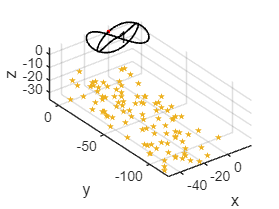

sigma_if=1*ones(5,1);

dt_update=0.05;
% m_data=gen_measurement_SE3(Eff_Range, T_feature, A, sigma_if, sigma_ij, trigK, Position0, T_WORKING, dt_update);
m_data=gen_measurement_SE3_single(landmarks,sigma_if, trigK, Position0, T_WORKING, dt_update);


% Parameters related with camera
sigma_cam=1;  % pixels
fx=460;
fy=460;
cx=255;
cy=255;
image_w=640;
image_h=640;
p_camera_in_IMU_real = [0.0, 0.0, 0.0]/scale;
R_camera_in_IMU_real = angle2dcm(0,0 , 0);
dtc=0.04;
%Generate camera landmarks.
N_LMCAMERA=100;
lm_camera=camera_genlandmark(N_LMCAMERA,[-5,-45,0],[45,120,30]); %generate camera's landmarks, 5*5=25

CAM_INTRISIC.FOV=pi/3;
CAM_INTRISIC.fx=fx;
CAM_INTRISIC.fy=fy;
CAM_INTRISIC.cx=cx;
CAM_INTRISIC.cy=cy;    
CAM_INTRISIC.image_w=image_w;
CAM_INTRISIC.image_h=image_h;
CAM_INTRISIC.tc=dtc; 
CAM_INTRISIC.sigma_cam=sigma_cam;

cam_data= camera_gendata(CAM_INTRISIC, lm_camera, (T_WORKING+dtc), p_camera_in_IMU_real, R_camera_in_IMU_real,dtc, Position0,trigK); 

landmark number mean:
15.8253


### Save New Data

folder='dataset'; 
if exist(folder)==0 
    mkdir(folder); 
end

save("dataset/data_s1.mat");


